## Infection, vaccination, and herd immunity

This case study introduces a model that describes infection as it affects an isolated population, explores the effect of vaccination, and demonstrates "herd immunity".

### Introduction

Every year at Olin College, about 90 new students come to campus from around the country and the world. Most of them arrive healthy and happy, but usually at least one brings with them some kind of infectious disease. A few weeks later, predictably, some fraction of the incoming class comes down with what we call “The Freshman Plague".

Inspired by this annual outbreak, we'll explore a well-known model of infectious disease, the SIR model, so-named because it considers three categories of people:

-   **S**: People who are “susceptible", that is, capable of contracting the disease if they come into contact with someone who is infected.

-   **I**: People who are “infectious", that is, capable of passing along the disease if they come into contact with someone susceptible.

-  **R**: People who are “recovered". In the basic version of the model, people who have recovered are considered to be immune to reinfection. That is a reasonable model for some diseases, but not for others, so it should be on the list of assumptions to reconsider later.

Let’s think about how the number of people in each category changes over time. Suppose we know that people with the disease are infectious for a period of 4 days, on average. If 100 people are infectious at a particular point in time, and we ignore the particular time each one became infected, we expect about 1 out of 4 to recover on any particular day.

Putting that a different way, if the time between recoveries is 4 days, the recovery rate is about 0.25 recoveries per day, which we’ll denote with the Greek letter $$\gamma$$ or the variable name `gamma`.

If the total number of people in the population is $$N$$, and the fraction currently infectious is $ $i$$, the total number of recoveries we expect per day is $$\gamma i N$$.

Now let’s think about the number of new infections. Suppose we know that each susceptible person comes into contact with 1 person every 3 days, on average, in a way that would cause them to become infected if the other person is infected. We’ll denote this contact rate with the Greek letter $$\beta$$ or the variable name `beta`.

It’s probably not reasonable to assume that we know $$\beta$$ ahead of time, but later we’ll see how to estimate it based on data from previous outbreaks.

If $$s$$ is the fraction of the population that’s susceptible, $$s N$$ is the number of susceptible people, $$\beta s N$$ is the number of contacts per day, and $$\beta s i N$$ is the number of those contacts where the other person is infectious.

In summary:

-   The number of recoveries we expect per day is $$\gamma i N$$; dividing by $$N$$ yields the fraction of the population that recovers in a day, which is $$\gamma i$$.

-   The number of new infections we expect per day is $$\beta s i N$$; dividing by $$N$$ yields the fraction of the population that gets infected in a day, which is $$\beta s i$$.

This model assumes that the population is isolated; that is, no one arrives or departs, so the size of the population, $$N$$, is constant.

### The SIR equations

Based on these infection and recovery rates, we can write differential equations that describe the rates of change for $ $s$$, $$i$$, and $$r$$ (where $$r$ $ is the fraction of the population that has recovered):


$$$\frac{ds}{dt} = -\beta s i$
$$



$$$\frac{di}{dt} = \beta s i - \gamma i$
$$



$$$\frac{dr}{dt} = \gamma i$
$$


To avoid cluttering the equations, I leave it implied that $ $s$$ is a function of time, $$s(t)$$, and likewise for $$i$$ and $$r$$.

Now let's implement these equations in MATLAB.  I'll store the parameters in an object named `params`.  I've chosen these parameters to yield behavior similar to what we see with the Freshman Plague.

clear all
params.beta = 1/3;    % infections per interaction per day
params.gamma = 1/4;   % recoveries per person per day

I represent the initial condition with a vector that contains the number of people who are susceptible, infected, and resistant.  This vector is normalized so the elements are fractions of the population rather than counts.

init = [89, 1, 0];
init = init / sum(init);
params.init = init

params = struct with fields:
     beta: 0.3333
    gamma: 0.2500
     init: [0.9889 0.0111 0]


At the end of this file, you'll find `run_ode_solver`, which takes `params`, simulates the system using `ode45`, and returns the results.

[T, M] = run_ode_solver(params);

`T` is a vector of times (in days).  `M` is a matrix with row for each time step and one column for each of S, I, and R.  `plot_results` is a function that plots the colums of `M` as lines and labels the axes.

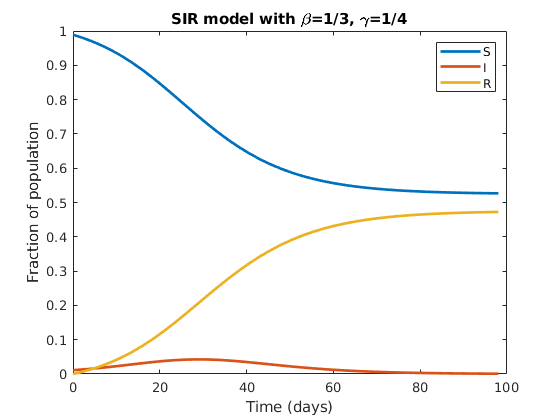

plot_results(T, M)

We can compute the total number of students who get the plague by computing the difference between S at the beginning and S at the end.

S = M(:, 1);
total_infected = S(1) - S(end) 

total_infected = 0.4622

### Vaccination

Models like this are useful for testing "what if?" scenarios.  As an example, we'll consider the effect of vaccination.

Suppose there is a vaccine that causes a student to become immune to the Freshman Plague without being infected.  How might you modify the model to capture this effect?

One option is to treat vaccination as a shortcut from susceptible to recovered without going through the infectious state.  The function `add_immunization` (at the end of this file) moves the given fraction of the population from S to R.  

If we assume that 10% of students are vaccinated at the beginning of the semester, and the vaccine is 100% effective, we can simulate the effect like this:

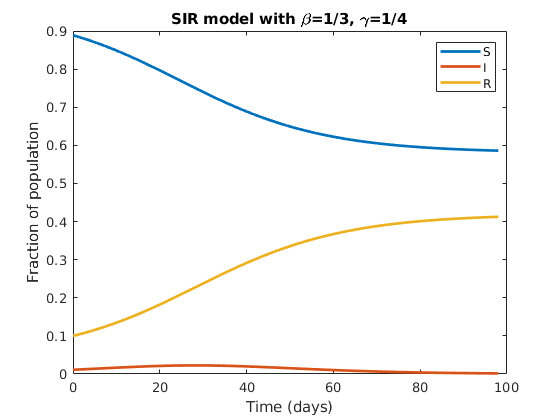

params.init = add_immunization(init, 0.1);
[T, M] = run_ode_solver(params);
plot_results(T, M)

And we can compute the total number of infections.

S = M(:, 1);
total_infected = S(1) - S(end) 

total_infected = 0.3029

Without vaccination, almost 47% of the population gets infected at some point.  With 10% vaccination, only 31% gets infected.  That's pretty good.

Now let's see what happens if we administer more vaccines.  The following looop sweeps a range of vaccination rates and computes the total number of student 

immune_rates = linspace(0, 1, 11);
infected_sweep = zeros(size(immune_rates));

for i = 1:length(immune_rates)
    fraction = immune_rates(i);
    params.init = add_immunization(init, fraction);
    [T, M] = run_ode_solver(params);
    S = M(:, 1);
    infected_sweep(i) = S(1) - S(end);
end

Now we can plot total number of infections as a function of vaccination rate:

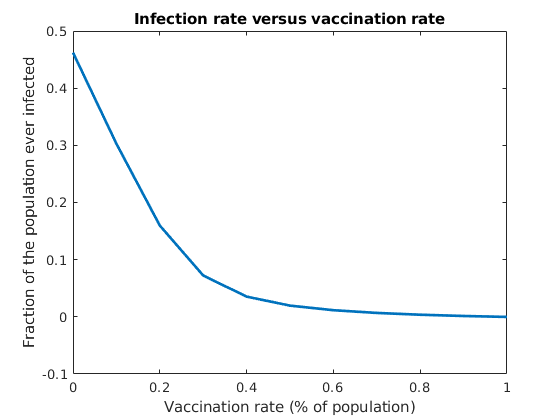

plot(immune_rates, infected_sweep)
xlabel('Vaccination rate (% of population)')
ylabel('Fraction of the population ever infected')
title('Infection rate versus vaccination rate')

As the immunization rate increases, the number of infections drops steeply.  If 40% of the students are immunized, fewer than 4% get sick.  That's because immunization has two effects: it protects the people who get immunized (of course) but it also protects the rest of the population. 

Reducing the number of "susceptibles" and increasing the number of "resistants" makes it harder for the disease to spread, because some fraction of contacts are wasted on people who cannot be infected.  This phenomenon is called **herd immunity**, and it is an important element of public health (see [https://en.wikipedia.org/wiki/Herd_immunity](https://en.wikipedia.org/wiki/Herd_immunity)).

The steepness of the curve in the previous figure is a blessing and a curse.  It's a blessing because it means we don't have to immunize everyone, and vaccines can protect the "herd" even if they are not 100% effective.

But it's a curse because a small decrease in vaccination can cause a big increase in infections.  In this example, if we drop from 80% vaccination to 60%, that might not be too bad.  But if we drop from 40% to 20%, that would trigger a major outbreak, affecting more than 15% of the population.  For a serious disease like measles, just to name one, that would be a public health catastrophe.

One use of models like this is to demonstrate phenomena like herd immunity and to predict the effect of interventions like vaccination.

### Compartment models

The SIR model is an example of a **compartment model**, so-called because it divides the world into discrete categories, or compartments, and describe transitions from one compartment to another. Compartments are also called **stocks** and transitions between them are called **flows**.

In this example, there are three stocks—susceptible, infectious, and recovered—and two flows—new infections and recoveries. Compartment models are often represented visually using stock and flow diagrams like this one:

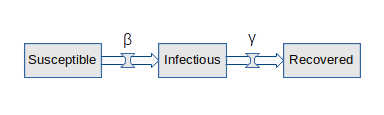

Stocks are represented by rectangles, flows by arrows. The widget in the middle of the arrows represents a valve that controls the rate of flow; the diagram shows the parameters that control the valves.

You can read more about stock and flow diagrams at [https://en.wikipedia.org/wiki/Stock_and_flow](https://en.wikipedia.org/wiki/Stock_and_flow)

### Functions

function [T, M] = run_ode_solver(params)
    % Simulate the SIR model for 14 weeks.
    
    % Test the slope function
    slope_func(0, params.init);
    
    % Run ode45
    tspan = [0, 7*14];
    [T, M] = ode45(@slope_func, tspan, params.init);
    
    function res = slope_func(t, X)
        % Compute the derivatives of the SIR model.
        [s, i, r] = matsplit(X);
    
        % compute new infections and recoveries
        infected = params.beta * i * s;
        recovered = params.gamma * i;
        
        % compute the derivatives
        dsdt = -infected;
        didt = infected - recovered;
        drdt = recovered;
        
        res = [dsdt; didt; drdt];
    end
end

function plot_results(T, M)
    % Plot the results of the SIR model
    plot(T, M)
    legend('S', 'I', 'R')
    xlabel('Time (days)')
    ylabel('Fraction of population')
    title('SIR model with \beta=1/3, \gamma=1/4')
end

function res = add_immunization(init, fraction)
    % Model immunization be moving the given fraction
    % of the population from S to R.
    res = init;
    res(1) = res(1) - fraction;
    res(3) = res(3) + fraction;
end

function varargout = matsplit(A,dim)
%MATSPLIT Split matrix elements into separate variables.
%   VARARGOUT = MATSPLIT(A) returns each element of the array A in a
%   separate variable defined by VARARGOUT.
%
%   VARARGOUT = MATSPLIT(A,DIM) only splits the matrix in one dimension. If
%   DIM=1, each column vector is assigned to an output variable. If
%   DIM=2, each row vector is assigned to an output variable.
%
%   MRE 11/12/14 (last updated 11/13/14)
%   https://www.mathworks.com/matlabcentral/fileexchange/48439-matsplit
    if nargin==1
        varargout = num2cell(A);
    else
        varargout = num2cell(A,dim);
    end
end